# Control de estados LQI

clear

g = 9.81;
psi_d = deg2rad(0);
a = g*sin(psi_d);
b = g*cos(psi_d);
c = -g*cos(psi_d);
d = g*sin(psi_d);

m = 1.6;
Jn = [0.021915027 0.022124548 0.042349865];
Ts = 1/510;
                
A = [0 1 zeros(1,6);
    zeros(1,8);
    zeros(3,5) eye(3);
    zeros(3,8)];
B = [zeros(1,4);
    1/m 0 0 0;
    zeros(3,4);
    zeros(3,1) diag(1./Jn)];
C = [1 0 0 0 0 0 0 0;
     0 0 1 0 0 0 0 0;
     0 0 0 1 0 0 0 0;
     0 0 0 0 1 0 0 0];
D = zeros(size(C,1),4);
        sys = ss(A,B,C,D, 'StateName',{'z', 'vz', 'phi', 'theta', 'psi', 'p', 'q', 'r'}, 'InputName', {'F', 'Tx', 'Ty', 'Tz'}, 'OutputName', {'z', 'phi', 'theta', 'psi'});
fprintf("Matriz de controlabilidad rango: %d", rank(ctrb(sys.A,sys.B)))

Matriz de controlabilidad rango: 8

fprintf("Matriz de Observabilidad rango: %d", rank(obsv(sys.A,sys.C)))

Matriz de Observabilidad rango: 8

dsys = c2d(sys, Ts,'zoh');

## LQI Continuo

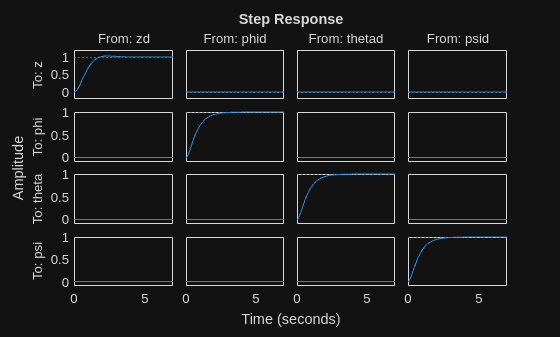

% lqi para modelo reducido a 8 estados
Q = diag([0.5 0.5 200 200 200 10 10 10 8 500 500 500]);
R = diag(0.0001*ones(1,4));
% AA = [zeros(size(sys.C,1)+size(sys.A,1),size(sys.B,2)) [sys.C;sys.A]];
% BB = [zeros(size(sys.B,2),size(sys.B,2));sys.B];
AA = [[sys.A;-sys.C] [zeros(size(sys.A,1),size(sys.B,2));zeros(size(sys.C,1));]];
BB = [sys.B; zeros(size(sys.B,2),size(sys.B,2))];
[K,~,P] = lqr(AA,BB,Q,R);
As = AA-BB*K;
Bs = [zeros(size(sys.A,1),size(sys.B,2));eye(size(sys.B,2))];
Cs = [sys.C zeros(size(sys.C,1),size(sys.B,2))];
Ds = zeros(size(sys.C,1),size(sys.B,2));
sysc = ss(As,Bs,Cs,Ds,'StateName',{'z', 'vz', 'phi', 'theta', 'psi', 'p', 'q', 'r', 'ez', 'ephi', 'etheta', 'epsi'}, 'InputName', {'zd', 'phid', 'thetad', 'psid'}, 'OutputName', {'z', 'phi', 'theta', 'psi'});
step(sysc)

% Observador
L = place(sys.A',sys.C',5*P(5:end))';

## LQI Discreto

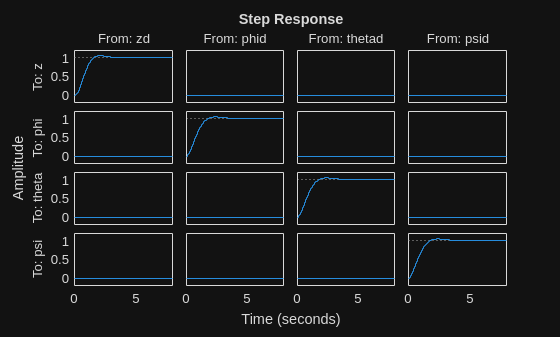

Q = diag(power([10 0.1 deg2rad([25 25 25 0.1 0.1 0.1]) 10 deg2rad([15 15 15])],-2));
R = diag(power([1 4 4 4],-2));
AA = [[dsys.A;-dsys.C] [zeros(size(dsys.A,1),size(dsys.B,2));eye(size(dsys.C,1));]];
BB = [dsys.B; zeros(size(dsys.B,2),size(dsys.B,2))];
[dK,~,e] = dlqr(AA,BB,Q,R);
As = AA-BB*dK;
Bs = [zeros(size(dsys.A,1),size(dsys.B,2));eye(size(dsys.B,2))];
Cs = [dsys.C zeros(size(dsys.C,1),size(dsys.B,2))];
Ds = zeros(size(dsys.C,1),size(dsys.B,2));
step(ss(As,Bs,Cs,Ds,Ts,'StateName',{'z', 'vz', 'phi', 'theta', 'psi', 'p', 'q', 'r', 'ez', 'ephi', 'etheta', 'epsi'}, 'InputName', {'zd', 'phid', 'thetad', 'psid'}, 'OutputName', {'z', 'phi', 'theta', 'psi'}))

dL = place(sys.A',sys.C',power(e(1:8),5))';